load("src\zadanie_06.mat")

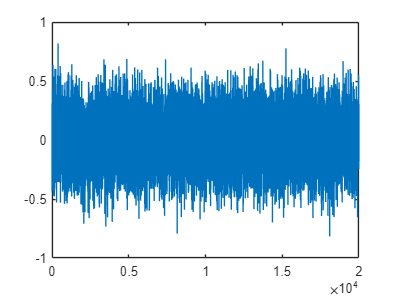

figure
plot(y)

handle = @(th) l_fun(th, y, A, B, G, C)

handle = function_handle with value:
    @(th)l_fun(th,y,A,B,G,C)


handle_test = @(th_1, th_2) l_fun_test(th_1, th_2, y, A, B, G, C)

handle_test = function_handle with value:
    @(th_1,th_2)l_fun_test(th_1,th_2,y,A,B,G,C)


lb = [0,0];
ub = [100,100];
a = [];
b = [];
Aeq = [];
beq = [];
x0 = [0, 0]

x0 =      0     0


[theta_min, min_value] = fmincon(handle,x0,a,b,Aeq,beq,lb,ub)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


theta_min =     1.9957    0.1999


min_value = -1.0998

[x_e, y_e] = estimated_output(theta_min, y, A, B, G, C);

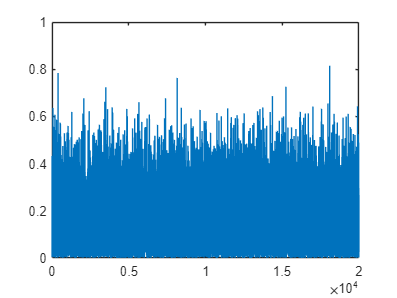

figure
plot(abs(y - y_e))

function q=l_fun(th, y, A, B, G, C)

[nx, ~] = size(A);
N = length(y);
th = th.^2;
q = 0;
m = zeros(nx, 1);
S = zeros(nx, nx);
u = 0;
for k = 1:N - 1
   m = A*m + B*u;
   S = A*S*A' + (G*G') * th(1);
   W = th(2) + C*S*C';
   e = y(k + 1) - C*m;
   q = (k - 1) * q/k + (e*e/W + log(W))/k;
   S = S - (S*(C' * C)*S)/W;
   m = m+S*C'*e/th(2);
end
q = 0.5 * q;
end


function [x_e, y_e] = estimated_output(th, y, A, B, G, C)

[nx, ~] = size(A);
N = length(y);
th = th.^2;
m = zeros(nx, 1);
S = zeros(nx, nx);
x_e = zeros(N, nx);
y_e = zeros(N, 1);
u = 0;
for k = 1:N - 1
   m = A*m + B*u;
   S = A*S*A' + (G*G') * th(1);
   W = th(2) + C*S*C';
   e = y(k + 1) - C*m;
   S = S - (S*(C' * C)*S)/W;
   m = m+S*C'*e/th(2);
   x_e(k, :) = m;
   y_e(k) = C*m;
end
end


% function q=l_fun_test(th_1, th_2, y, A, B, G, C)
% 
% [nx, ~] = size(A);
% N = length(y);
% th = [th_1, th_2];
% th = th.^2;
% q = 0;
% m = zeros(nx, 1);
% S = zeros(nx, nx);
% u = 0;
% for k = 1:N - 1
%    m = A*m + B*u;
%    S = A*S*A' + (G*G') * th(1);
%    W = th(2) + C*S*C';
%    e = y(k + 1) - C*m;
%    q = (k - 1) * q/k + (e*e/W + log(W))/k;
%    S = S - (S*(C' * C)*S)/W;
%    m = m+S*C'*e/th(2);
% end
% q = 0.5 * q;
% end